# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 5.6.2 Inverse Filtering

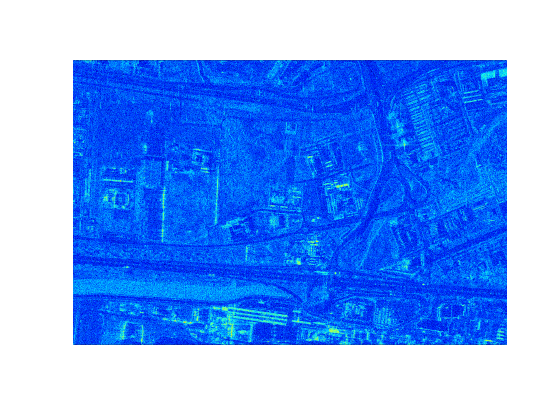

[file,path] = uigetfile('*.h5');
filename = fullfile(path,file);

% Form the complex data
s_i = h5read(filename, '/s_i');
s_q = h5read(filename, '/s_q');
s = double(s_i) + 1j * double(s_q);

clear s_i s_q

% Dynamic range for the image
dynamic_range = 75;

% Data size
[nx, ny] = size(s);
ratio = ny/nx;

% Pixel offset from image center
offset_x = 0;
offset_y = 0;

xc = round(nx/2) - offset_x;
yc = round(ny/2) - offset_y;

% Specify a span / or fixed aspect
xs = 750;
ys = 5000;
% ys = round(ratio * xs);

% For full image
% xs = nx/2-1;
% ys = ny/2-1;

% Calculate the image indices
index_x = xc-xs:xc+xs;
index_y = yc-ys:yc+ys;

% For specifying a particular location in the image
index_x = (1:2000) + 1000;
index_y = (1:8000);

% Extract the desired portion of the image
xs = round( (index_x(end) - index_x(1)) / 2);
ys = round( (index_y(end) - index_y(1)) / 2);
s = s(index_x, index_y);  [nx, ny] = size(s);

% Generate the phase error
t = linspace(-1.3, 0.5, nx);
phi = 10 * (4 * t.^3 + 6 * t.^2);

% Apply the phase error
phase_term = exp(1j * phi') * ones(1, ny);
sf = fftshift(fft(s, [], 1), 1);
s_e = ifft(phase_term .* sf);

% Estimate the phase error
% Use center shift of bright targets (then choose range line)
% Then select and estimate window
img = s';
center_az_idx = ceil(size(img, 2)/2);

[tmp, maximum_along_az_idx] = max(abs(img), [], 2);

for i = 1:size(img, 1)
    img(i,:) = circshift(transpose(img(i,:)), center_az_idx - maximum_along_az_idx(i));
end

% Use range line 462 with span of +/-50
ss = img(462,:);
ss(1:center_az_idx - 50) = 0;
ss(center_az_idx + 50:end) = 0;
point_target = ss;

% Unwrap the phase of the point target
phase_error = unwrap(angle(fft(point_target)));

% Correct the image
phase_term = exp(-1j * phase_error') * ones(1, ny);
s_ef = (fft(s_e, [], 1));
s_c = ifft(phase_term .* s_ef);

% Original image
figure
pcolor(flipud(db(s)')); shading flat; 
% imshow(db(s))
colormap jet
set(gca,'XTick',[], 'YTick', [])
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])

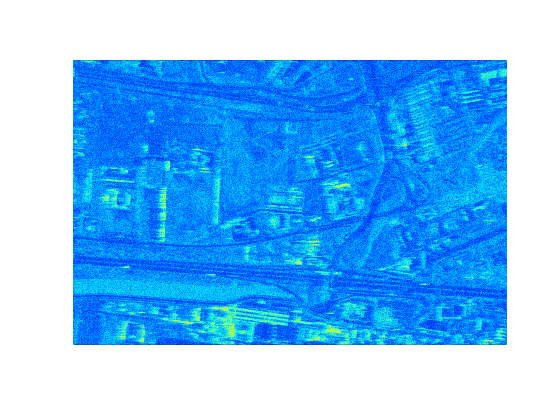



% Corrupted image
figure
pcolor(flipud(db(s_e)')); shading flat; 
% imshow(db(s_e))
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
pbaspect([ratio * xs / ys 1 1])

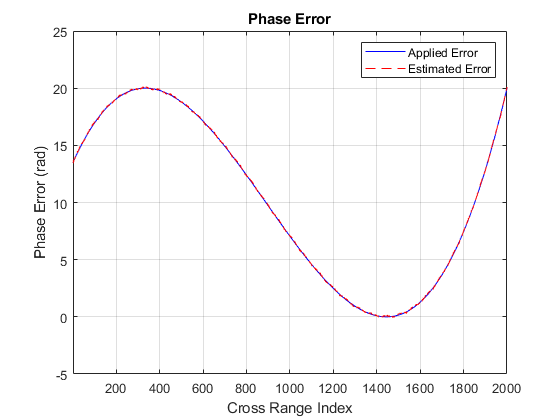



% Compare the phase error vs applied error
figure
plot(phi, 'b'); hold on;
plot(phase_error, 'r--'); 
xlim([1, nx])
title('Phase Error'); 
ylabel('Phase Error (rad)');
xlabel('Cross Range Index');
grid on
legend('Applied Error', 'Estimated Error');

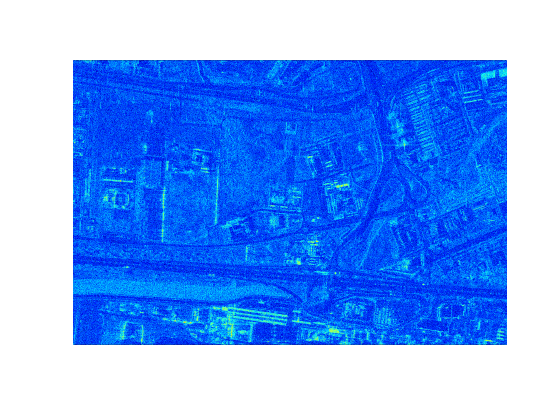



% Corrected image
figure
pcolor(flipud(db(s_c)')); shading flat; 
% imshow(db(s_c))
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])